# Hand Gesture Classifier - 2nd Section of Code

clc; clear; close all;

## Load Pretrained Network

% For AlexNet Model "Loading pretrained AlexNet Model"
disp("Loading pretrained ResNet18 model...");

Loading pretrained ResNet18 model...


% For AlexNet Model repllace with 'TrainedHandGestureModel_AlexNet.mat'
load('TrainedHandGestureModel_Project2.mat', 'trainedNet');
classNames = trainedNet.Layers(end).Classes;
inputSize = trainedNet.Layers(1).InputSize;
numClasses = numel(classNames);

## Select Images for Classification

disp("Select image(s) for classification:");

Select image(s) for classification:


[files, path] = uigetfile({'*.jpg;*.jpeg;*.png;*.bmp', 'Image Files (*.jpg, *.png, *.bmp)'}, ...
    'Select One or More Images', 'MultiSelect', 'on');

% Exit if no files were selected
if isequal(files, 0)
    disp("No files selected. Exiting...");
    return;
end

% Ensure files are in a cell array format
if ischar(files)
    files = {files};
end

numFiles = numel(files);

% Preallocate storage
fileNames = strings(numFiles, 1);
topPredictions = strings(numFiles, 1);
topScores = zeros(numFiles, 1);
allScoresMatrix = zeros(numFiles, numClasses);

## Loop Over Images for Prediction and Display

Image 1 (Fist.jpg): 0.16 sec | Predicted: Fist (100.0%)
Image 2 (Heart.jpg): 0.03 sec | Predicted: Heart (99.9%)
Image 3 (Okay.jpg): 0.03 sec | Predicted: Okay (100.0%)
Image 4 (Okay-2.jpg): 0.03 sec | Predicted: Heart (63.0%)
Image 5 (Peace (2).jpeg): 0.03 sec | Predicted: Okay (65.1%)
Image 6 (Peace.jpeg): 0.03 sec | Predicted: Peace (95.0%)
Image 7 (Peace-3.jpeg): 0.03 sec | Predicted: Peace (85.3%)
Image 8 (Thumb_Up.jpg): 0.03 sec | Predicted: Thumbs_Up (98.9%)


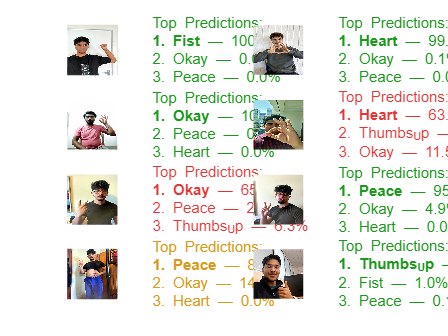

for i = 1:numFiles
    % ---- Load and preprocess image ----
    imgPath = fullfile(path, files{i});
    img = imread(imgPath);
    img = imresize(img, inputSize(1:2));  % Resize to match model input size

    % Convert grayscale to RGB if needed
    if size(img, 3) == 1
        img = cat(3, img, img, img);
    end

    % Enhance contrast and sharpness
    imgAdj = zeros(size(img), 'like', img);
    for ch = 1:3
        imgAdj(:,:,ch) = imadjust(img(:,:,ch));
    end
    img = imsharpen(imgAdj);

    % ---- Predict gesture using ResNet18 (original + flipped ensemble) ----
    % Classification using Test-time Augmentation (TTA)
    tic;
    [~, score1] = classify(trainedNet, img);
    [~, score2] = classify(trainedNet, fliplr(img));
    elapsedTime = toc;
    finalScore = (score1 + score2) / 2;

    % Get top prediction and its confidence
    [sortedScores, sortedIdx] = sort(finalScore, 'descend');
    sortedClasses = classNames(sortedIdx);
    topPredictions(i) = string(sortedClasses(1));
    topScores(i) = sortedScores(1) * 100;
    allScoresMatrix(i, :) = finalScore;

    % ---- Display: LEFT TILE = Image ----
    ax1 = nexttile(2*i - 1);
    imshow(img, 'Parent', ax1);
    axis(ax1, 'image');
    set(ax1, 'XTick', [], 'YTick', []);

    % ---- Display: RIGHT TILE = Prediction Text ----
    ax2 = nexttile(2*i);
    axis(ax2, 'off');

    % Create prediction label text with Top-3 predictions
    predStr = sprintf('Top Predictions:\n\\bf1. %s\\rm — %.1f%%%', ...
        string(sortedClasses(1)), sortedScores(1)*100);
    for j = 2:3
        predStr = sprintf('%s\n%d. %s — %.1f%%%', ...
            predStr, j, string(sortedClasses(j)), sortedScores(j)*100);
    end

    % Set text color based on confidence level
    conf = topScores(i);
    if conf > 90
        textColor = [0.1 0.6 0.1];  % Green for high confidence
    elseif conf > 70
        textColor = [0.85 0.6 0.1]; % Orange for medium
    else
        textColor = [0.9 0.2 0.2];  % Red for low confidence
    end

    % Display prediction text beside image
    text(0, 0.5, predStr, ...
        'Units', 'normalized', ...
        'HorizontalAlignment', 'left', ...
        'VerticalAlignment', 'middle', ...
        'FontSize', 14, ...
        'Color', textColor, ...
        'Interpreter', 'tex', ...
        'Parent', ax2);

    % ---- Console Output ----
    fprintf("Image %d (%s): %.2f sec | Predicted: %s (%.1f%%)\n", ...
        i, files{i}, elapsedTime, topPredictions(i), topScores(i));
end